### AAE333 Lab1 Matlab Code

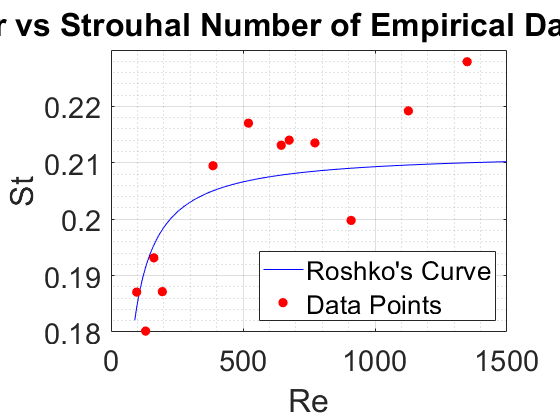

% Reading the excel files into matlab
file1 = readmatrix('datasheet_part1.xlsx');
file2 = readmatrix('datasheet_part2.xlsx');
file3 = readmatrix('datasheet_part4.xlsx');

% Setting variables
rho = 997; % Density of water [kg/m^3]
myu = 8.90*10^(-4); % Viscosity of water at room temperature [Pa.s]
% Velocities for all water tunnel speeds 30Hz - 60Hz
vel_col = file1(:,6); 
% Diameter of cylinders
d_col = file2(:,1);
% Karman Vortices shedding frequency for each cylinder diameter
n_30 = file2(:,4) / 60;
n_40 = file2(:,7) / 60;
n_50 = file2(:,10) / 60;
n_60 = file2(:,13) / 60;

% Reynold's numbers for 30Hz - 60Hz with each cylinder diameter
Re_30 = rho*vel_col(4,1).*d_col/myu; % Experimental Reynold's number 30Hz
Re_40 = rho*vel_col(3,1).*d_col/myu; % Experimental Reynold's number 40Hz
Re_50 = rho*vel_col(2,1).*d_col/myu; % Experimental Reynold's number 40Hz
Re_60 = rho*vel_col(1,1).*d_col/myu; % Experimental Reynold's number 40Hz
% Strouhal numbers for 30Hz - 60Hz with each cylinder diameter
S_30 = n_30 .* d_col / vel_col(4,1); % Experimental Strouhal number 30Hz
S_40 = n_40 .* d_col / vel_col(3,1); % Experimental Strouhal number 40Hz
S_50 = n_50 .* d_col / vel_col(2,1); % Experimental Strouhal number 50Hz
S_60 = n_60 .* d_col / vel_col(1,1); % Experimental Strouhal number 60Hz

% Concatenate vectors to create one vector with experimental Reynold's 
% number and Strouhal number
Re_exp = [Re_30' Re_40' Re_50' Re_60'];
S_exp = [S_30' S_40' S_50' S_60'];

% Plotting the accepted the empirical Reynolds - Strouhal number curve.
Re0 = linspace(90,1500,2^10); % Empirical Reynold's number
S0 = 0.212 * (1 - 12.7 ./ Re0); % Empirical Strouhal number 0<Re<100,000

figure(1)
plot(Re0, S0, '-b')
xlabel('Re')
ylabel('St')
title(['Reynold''s Number vs Strouhal Number of Empirical Data ' ...
    '- By: Tomoki Koike'])
grid on
grid minor 
box on
hold on 
plot(Re_exp, S_exp, '.r','MarkerSize',24)
hold off
legend('Roshko''s Curve', 'Data Points', 'location', 'southeast')
fig = gca;
fig.FontSize = 22;

## Analysis

figure(2)
plot(Re0, S0, '-b')
title(['Reynold''s Number vs Strouhal Number of Empirical Data ' ...
    '- By: Tomoki Koike'])
grid on
grid minor 
box on
hold on 
plot(Re_exp, S_exp, '.r','MarkerSize',24)
[result gof plt] = data_curve_fitting(Re_exp, S_exp);
plt

plt =   2×1 Line array:

  Line    (data)
  Line    (fitted curve)


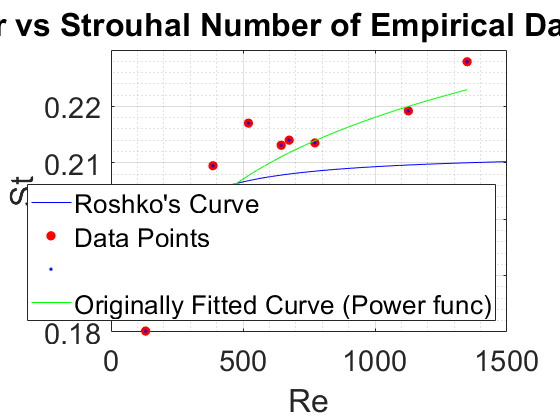

hold off
xlabel('Re')
ylabel('St')
legend('Roshko''s Curve', 'Data Points', '','Originally Fitted Curve (Power func)','location', 'southeast')
fig = gca;
fig.FontSize = 22;